Prepare some figures.

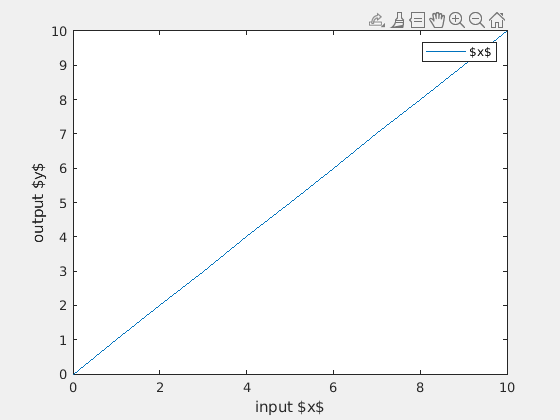

clear
close all

x = 0:10;
y(1,:) = x;
y(2,:) = x.^2;
y(3,:) = sqrt(x);
y(4,:) = sin(x);
figs = matlab.ui.Figure.empty();    % for arguments

figure('Name', 'liner', 'Visible', 'on');
plot(x, y(1,:));
xlabel('input $x$');
ylabel('output $y$');
legend('$x$', 'Location', 'northeast');

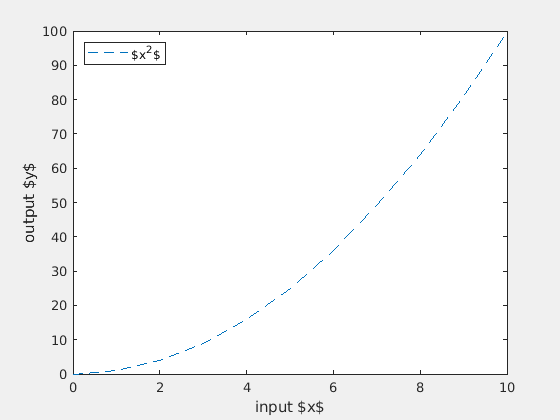


figure('Name', 'quadratic', 'Visible', 'on');
plot(x, y(2,:),"LineStyle","--");
xlabel('input $x$');
ylabel('output $y$');
legend('$x^2$', 'Location', 'northwest');

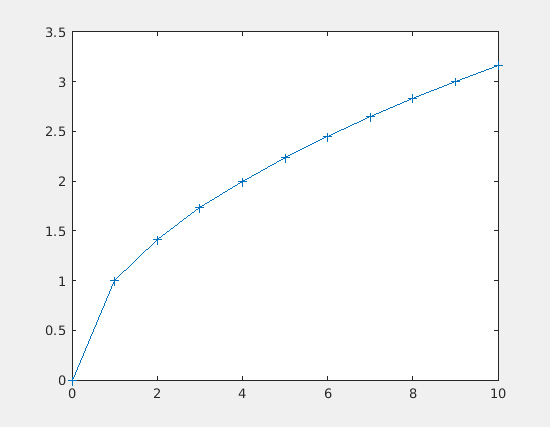


figure('Name', 'square root', 'Visible', 'on');
plot(x, y(3,:),"Marker","+");

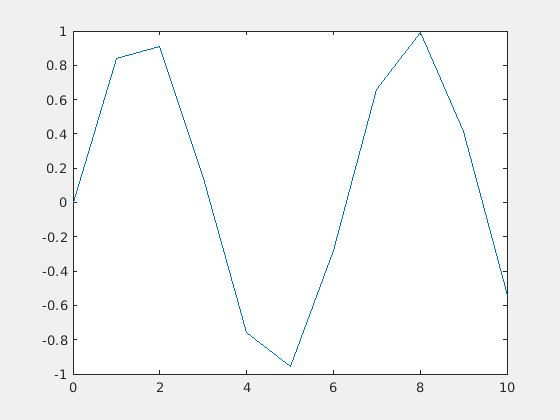

figs = [figs gcf];  % for arguments

figure('Name', 'sine curve', 'Visible', 'on');
plot(x, y(4,:));

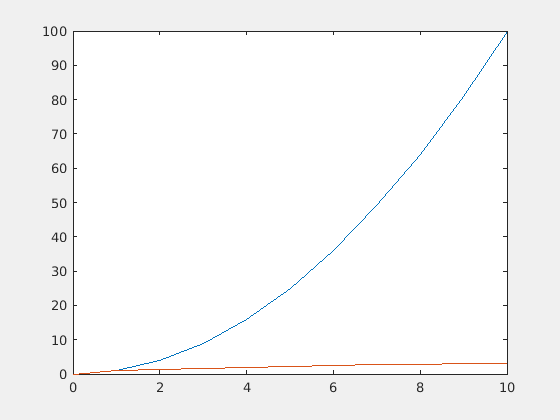

figs = [figs gcf];  % for arguments

figure('Name', '2 lines', 'Visible', 'on');
plot(x, y(2:3,:));

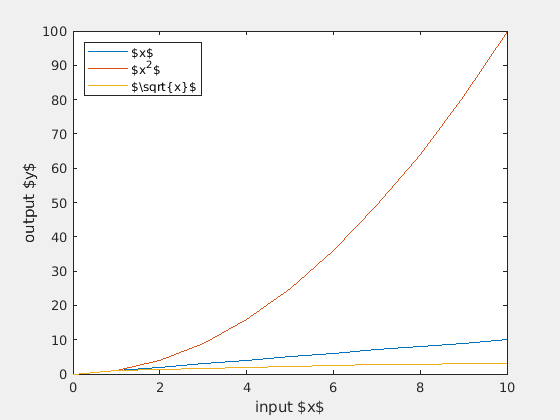

figs = [figs gcf];  % for arguments

figure('Name', '3 lines', 'Visible', 'on');
plot(x, y(1:3,:));
xlabel('input $x$');
ylabel('output $y$');
warning('off', 'MATLAB:handle_graphics:exceptions:SceneNode');
% warning('on')
legend('$x$', '$x^2$', '$\sqrt{x}$', 'Location', 'northwest');

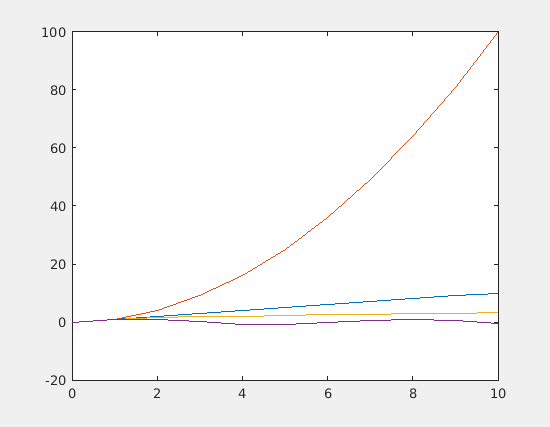

figs = [figs gcf];  % for arguments

% figure('Name', 'all lines', 'Visible', 'on');
figure('Visible', 'on');
plot(x, y);

Examples

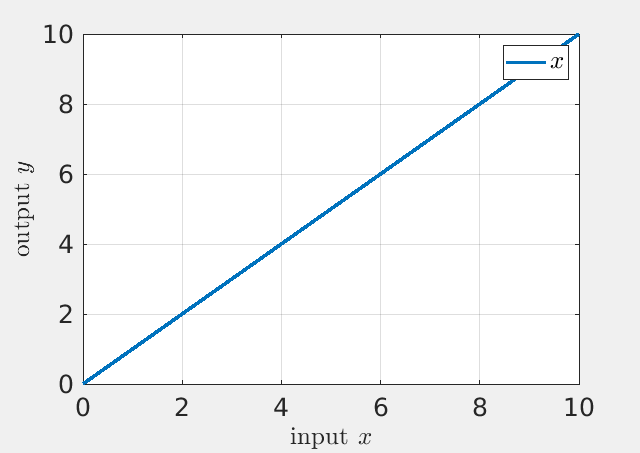

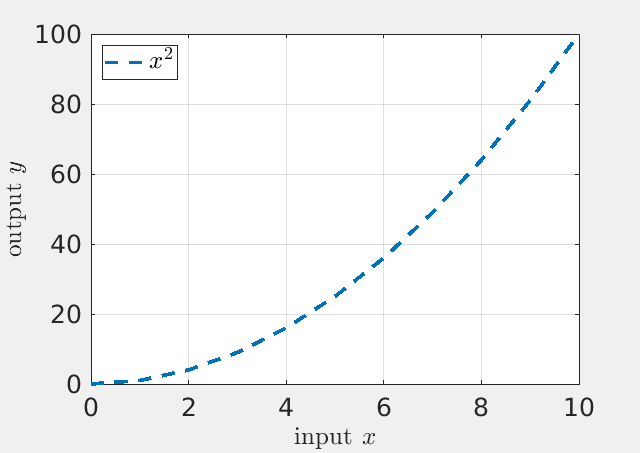

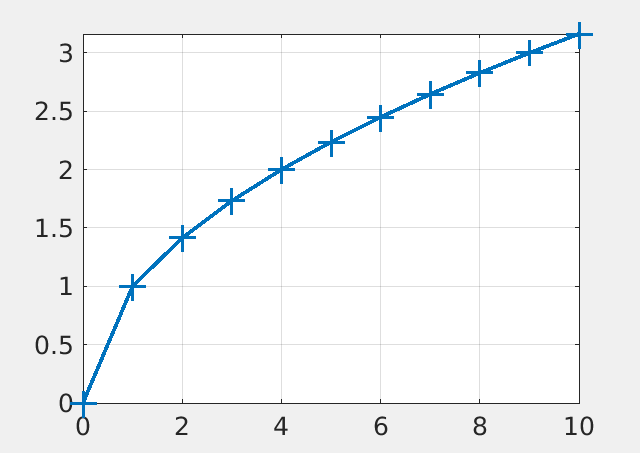

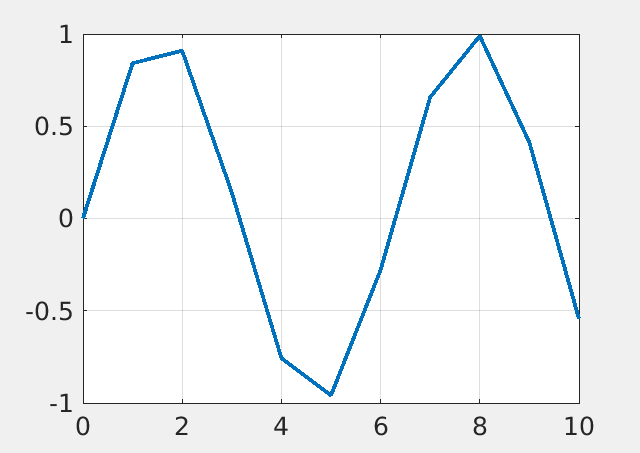

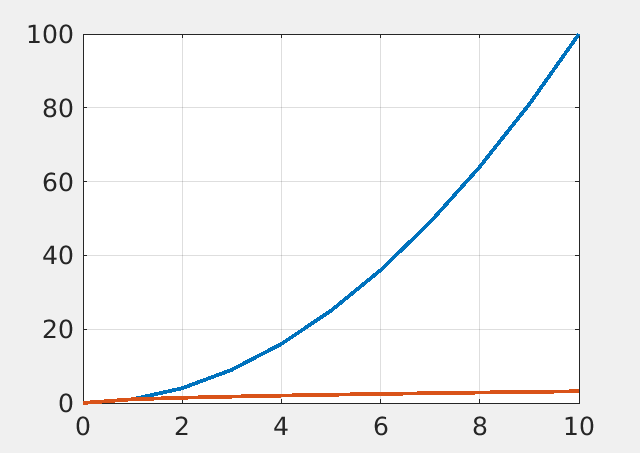

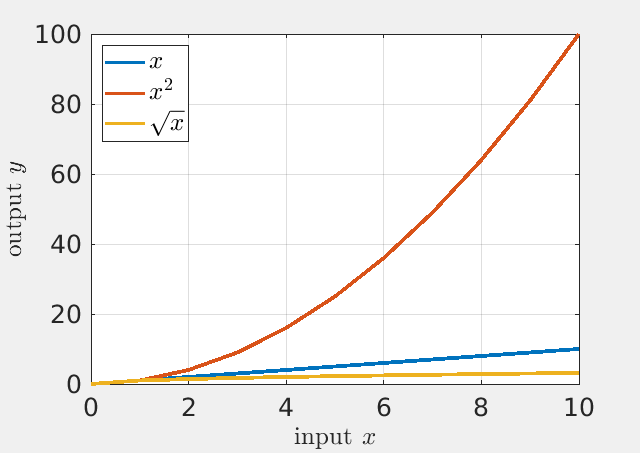

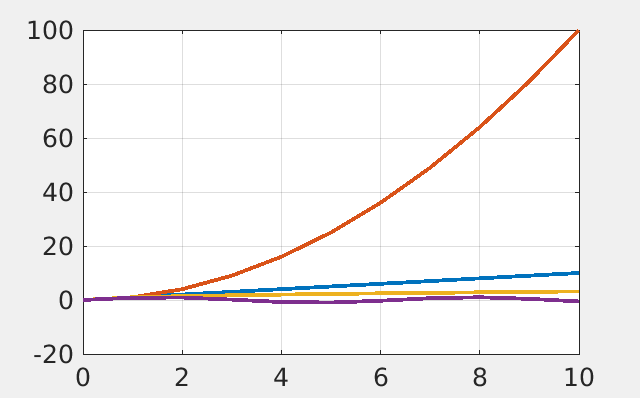

resizeAndArrangeFigures()

% resizeAndArrangeFigures(Figures=figs)
% resizeAndArrangeFigures(Division=[4,3])
% resizeAndArrangeFigures(Monitor=2)
% resizeAndArrangeFigures(ExportDir='fig')
% resizeAndArrangeFigures(Figures=figs, Division=[4,3], Monitor=2, ExportDir='fig')

% params.LineWidth = 5;
% params.MarkerSize = 30;
% resizeAndArrangeFigures(ExportParams=params)